# Noise inspection: White Noise

***This Script examines the influence of augmentation on white noise***

clc; close all; clear;
addpath(genpath(fullfile('../')));

## White noise examination

*We start from the assumption that the white noise signal is broadband and normally distributed.*

fs = 44100;                                % Sampling frequency of audio input
noise = randn(fs,1);    % Normally distributed white noise
noise = noise/max(noise);
t = 0:1/fs:(length(noise)-1)/fs;

*The noise sample will be augmented using the Impulse response with duration = 1000ms coming from the front direction*

% IR Set with Duration = 1000ms
nameIR1000ms = 'IR44K_2s_1000ms';
dir = "aux_data/IR_Z_fixed/2s/";
IR1000ms = load(dir+nameIR1000ms).IR44K_2s_1000ms;
IR1000ms =IR1000ms(:,2);
IR1000ms = [IR1000ms{:}];

% Augmentation
noise_aug = conv(noise,IR1000ms(:,1));       % Take only length of noise sample after convolution
noise_aug = noise_aug(1:fs);
noise_aug = noise_aug/max(noise_aug);

*Inspect the ****Power spectrum**** of the noise samples using the**** Welch Method***

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%       PSD Welch Method parameters     %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
segmentLength = 512;                    % Segments will be 512 samples (goes to 257 when taking positive frequencies only)
frame_overlap = segmentLength/2;        % 50 percent overlap
win = hamming(segmentLength);           % 512 sample-length hanning window
df = fs/(2*((segmentLength/2)+1));      %
f = 0:df:(fs-df)/2;                     %
N_bins = (segmentLength/2)+1;           %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% PSD estimation noise sample:
framed_fft = welch_window(noise, segmentLength, frame_overlap, win);
noise_psd = normalize(welch_input_fft(framed_fft, win, fs),'range');

% PSD estimation augmented noise sample:
framed_fft = welch_window(noise_aug, segmentLength, frame_overlap, win);
noise_aug_psd = normalize(welch_input_fft(framed_fft, win, fs),'range');

*Plot the time and frequency domain *

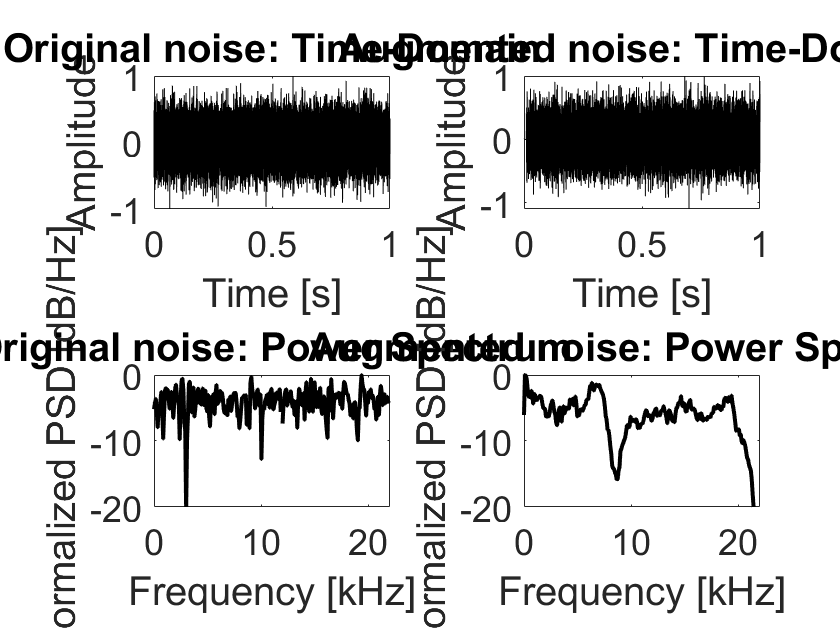

fig = figure;
fontsize = 18;
subplot(2,2,1); plot(t,noise, 'k'); xlabel("Time [s]"); ylabel("Amplitude"); title("Original noise: Time-Domain", "FontSize", 36); 
ax = gca;
ax.FontSize = fontsize;
subplot(2,2,2); plot(t,noise_aug, 'k'); xlabel("Time [s]"); ylabel("Amplitude"); title("Augmented noise: Time-Domain", "FontSize",36);
ax = gca;
ax.FontSize = fontsize;
subplot(2,2,3); plot(f/1000,10*log10(noise_psd), 'k', "LineWidth", 2); xlabel("Frequency [kHz]"); ylabel("Normalized PSD [dB/Hz]"); title("Original noise: Power Spectrum","FontSize",36); ylim([-20 0]);
xlim([0 22.050]);
ax = gca;
ax.FontSize = fontsize;
subplot(2,2,4); plot(f/1000,10*log10(noise_aug_psd), 'k', "LineWidth", 2); xlabel("Frequency [kHz]"); ylabel("Normalized PSD [dB/Hz]"); title("Augmented noise: Power Spectrum","FontSize",36); ylim([-20 0]);
xlim([0 22.050]);
ax = gca;
ax.FontSize = fontsize;

*We see that augmentation causes the same filtering effect as seen with the impulse response.*

*This can be explained as written in Chapter 4     of the thesis scripture*

## PSD for different Reverbs

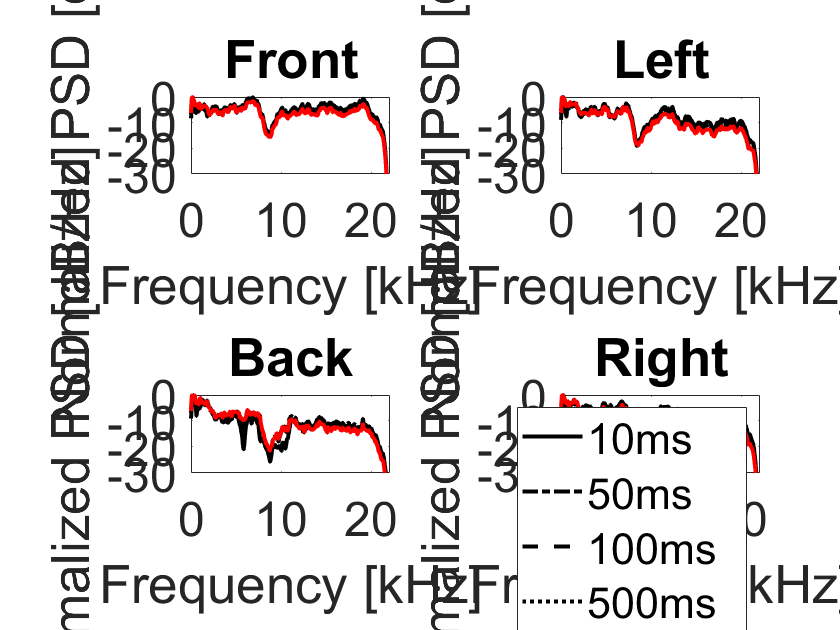

IRLen = 40;
fs = 44100;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth

% IR Set with Duration = 1000ms
nameIR1000ms = 'IR44K_2s_1000ms';
IR1000ms = load(dir+nameIR1000ms).IR44K_2s_1000ms;
IR1000ms =IR1000ms(:,2);
IR1000ms = [IR1000ms{:}];

% IR Set with Duration = 500ms
nameIR500ms = 'IR44K_2s_500ms';
IR500ms = load(dir+nameIR500ms).IR44K_2s_500ms;
IR500ms =IR500ms(:,2);
IR500ms = [IR500ms{:}];

% IR Set with Duration = 100ms
nameIR100ms = 'IR44K_2s_100ms';
IR100ms = load(dir+nameIR100ms).IR44K_2s_100ms;
IR100ms =IR100ms(:,2);
IR100ms = [IR100ms{:}];

% IR Set with Duration = 50ms
nameIR50ms = 'IR44K_2s_50ms';
IR50ms = load(dir+nameIR50ms).IR44K_2s_50ms;
IR50ms =IR50ms(:,2);
IR50ms = [IR50ms{:}];

% IR Set with Duration = 10ms
nameIR10ms = 'IR44K_2s_10ms';
IR10ms = load(dir+nameIR10ms).IR44K_2s_10ms;
IR10ms =IR10ms(:,2);
IR10ms = [IR10ms{:}];

IR_set = {IR10ms; IR50ms;IR100ms;IR500ms;IR1000ms};

noise = randn(fs,1);
lines = ["-"; "-."; "--"; ":";"-"];
colors = ["k";"k";"k";"k";"r"];
titles = ["Front", "Left", "Back", "Right"];

    
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%       PSD Welch Method parameters  f   %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
segmentLength = 512;                    % Segments will be 512 samples (goes to 257 when taking positive frequencies only)
frame_overlap = segmentLength/2;        % 50 percent overlap
win = hamming(segmentLength);           % 512 sample-length hanning window
df = fs/(2*((segmentLength/2)+1));      %
f = 0:df:(fs-df)/2;                     %
N_bins = (segmentLength/2)+1;           %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
fontsize = 24;
for i = 1:10:40
    index = ceil(i/10);
    for N = 1:5
        IR = IR_set{N};
        noise_aug = conv(noise,IR(:,i));
        noise_aug = noise_aug(1:fs);
        noise_aug = noise_aug/max(noise_aug);
    
        % PSD estimation noise sample:
        framed_fft = welch_window(noise_aug, segmentLength, frame_overlap, win);
        Pxx = normalize(welch_input_fft(framed_fft, win, fs),'range');
        subplot(2,2,index);plot(f/1000,10*log10(Pxx), "Color", colors(N), "LineStyle",lines(N), "LineWidth",2); hold on;
        xlabel("Frequency [kHz]"); ylabel("Normalized PSD [dB/Hz]");
        xlim([0 22.050]);
        ax = gca;
        ax.FontSize = fontsize;
    end
    
    title(titles(index));
    ylim([-30 0]);
end
legend("10ms", "50ms", "100ms", "500ms", "1000ms");
ax = gca;
ax.FontSize = fontsize;